# Metoda Geara

Najpierw implementuje zadana funkcje `rlc(t,x)`

clear all

Rozwiazujemy uklad dla `t=0:24 `i `dt=0.001 `przy pomocy metody **Geara**.

Tworzymy pierwsze 3 elementy `x `aby zastosowac metode **Geara**. Generuje je za pomoca algorytmu eulera /duhh/

global t;
t = 0:0.001:24;
% z jakiegos powodu bez tego len(t) = 24001
t = t(:,1:end-1);

x = zeros(3,4);
for i=1:3
    x(:,i+1) = x(:,i) + 0.001 * rlc(t(i), x(:,i));
end

x = gear(x,24*1000-4);

wykres pradu:

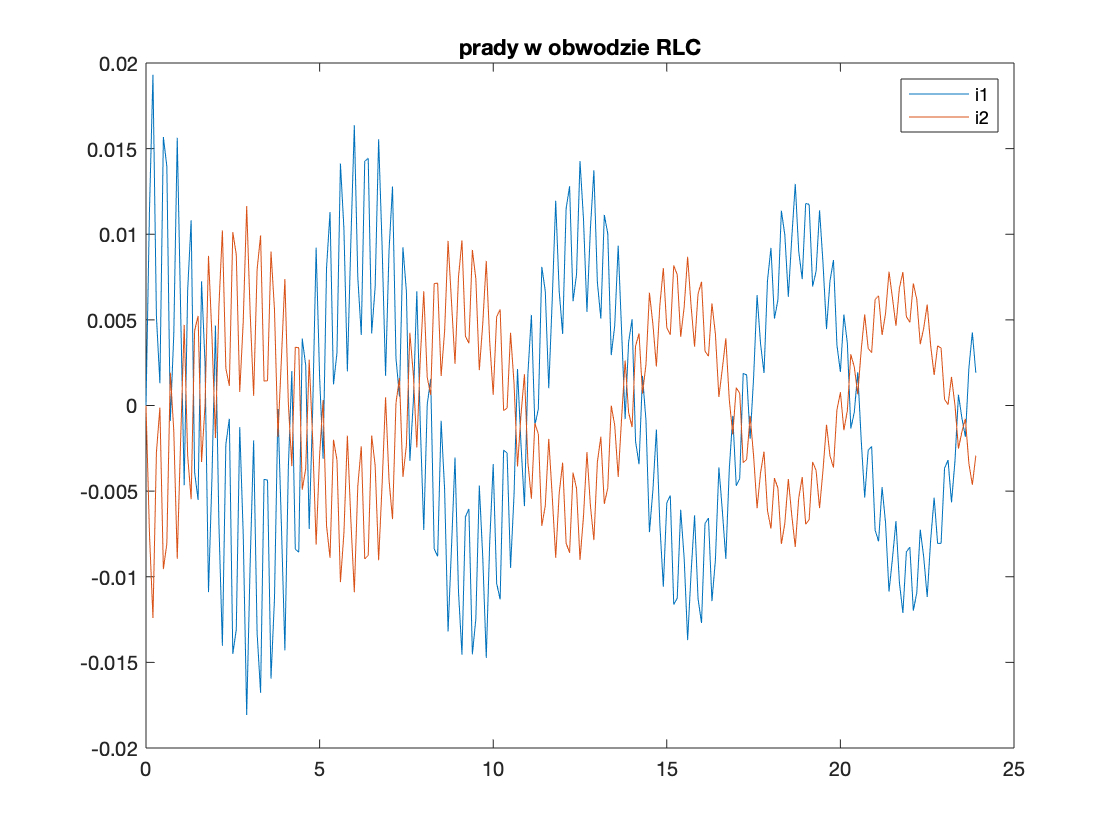

clf(1)
figure(1)
plot(t(1:100:end),x(1,1:100:end))
hold on
plot(t(1:100:end),x(2,1:100:end))
title("prady w obwodzie RLC")
legend("i1","i2")

wykres napiecia:

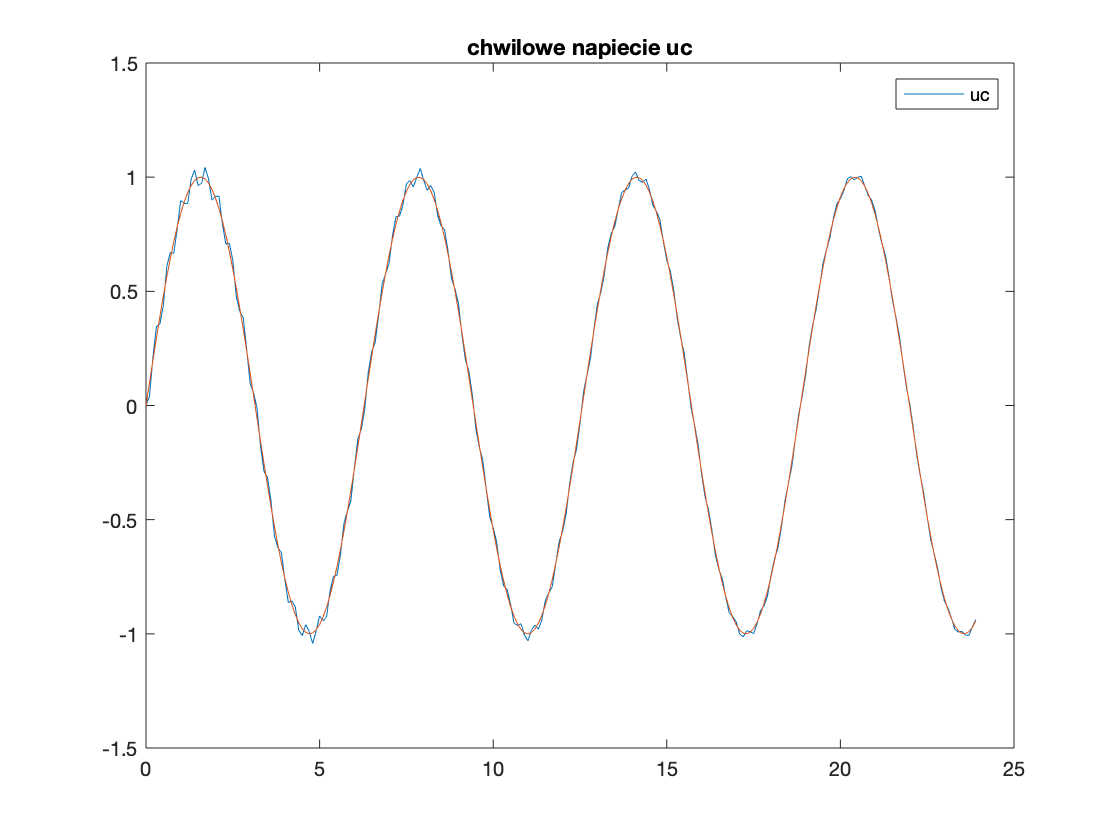

clf(2)
figure(2)
plot(t(1:100:end),x(3,1:100:end))
hold on
plot(t(1:100:end),sin(t(1:100:end)))
title("chwilowe napiecie uc")
legend("uc")

zaimplementowane funkcje:

function xprim = rlc(t,x)
    R1 = 0.02; R2 = 0.5; C = 0.01;
    L1 = 1; L2 = 1.5; M = 1;
    D = M / (L1*L2-M^2);
    
    A = [   -R1*L2*D/M R2*L2*D/L2 -L2*D/M;
            R1*D    -R2*L1*D/M          D;
            1/C         0               0   ];
    B = [L2*D/M; -D; 0];
    
    e = sin(t);
    
    xprim = A*x+B*e;
end


funkcja geara

function x = gear(x, i)
    global t;
    if i == 0
        return;
    end
    x(:, end+1) = 1/25*(48*x(:,end) - 36*x(:,end-1) + 16*x(:,end-2) - 3*x(:,end-3) + 12*0.001*rlc(t(size(x,2)), x(:,end)));
    x = gear(x, i-1);
end